**Variable and constant definitions**

clear;
hbar = 6.5821*10^-16;       % h bar
p = 1000;                   % precision

a = 0.2*10^-9;              % well width (m)
m = 0.51099895 * 10^6;      % partical mass (eV)

% energy level (any subset of positive intigers)
n = [2,4,5];                      

x = linspace(0,a,p);      % points along well
A = sqrt(2/a);              % normalization constant
K = (n*pi)/a;               % sine argument substitution

**Functions**

% potential function
U = 10^20*[ones(1,p/4) , zeros(1,p) , ones(1,p/4)];  

% wave function
psi = A*sin(K'*x);

% probability function
psiSTARpsi = psi.*conj(psi);

% energy at given state
E = n.^2*pi^2*hbar^2/(2*m*a^2)

E = 	1.0e+-14 *

    0.0418    0.1674    0.2615


**Plots**

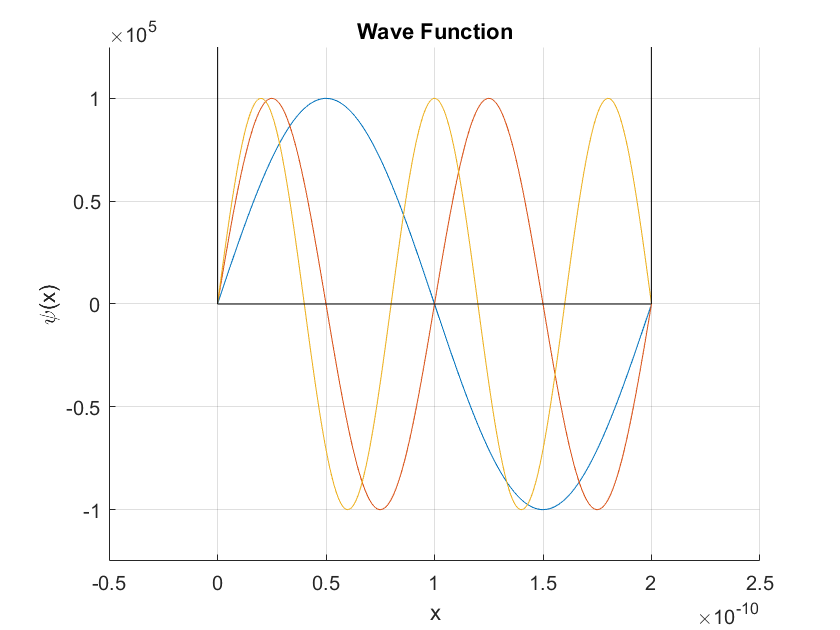

% wave function plot setup

figure;
size_n = size(n);   % size n for desired plot
hold on;

% plot adjustment for input energy levels (n)

if size_n(2) == 1
    plot(x,psi);
else
    for c = 1 : size_n(2)
        plot(x,psi(c,:));
    end
end

xU = linspace(-a/4,5*a/4,3*p/2);
plot(xU,U,'black'); % potential plot
hold off;

% wave function plot labels and such

title('Wave Function');ylabel('\psi(x)');xlabel('x');
axis([-a/4,a+a/4,...
    min(min(psi))+min(min(psi))/4,...
    max(max(psi))+max(max(psi))/4])
grid on;

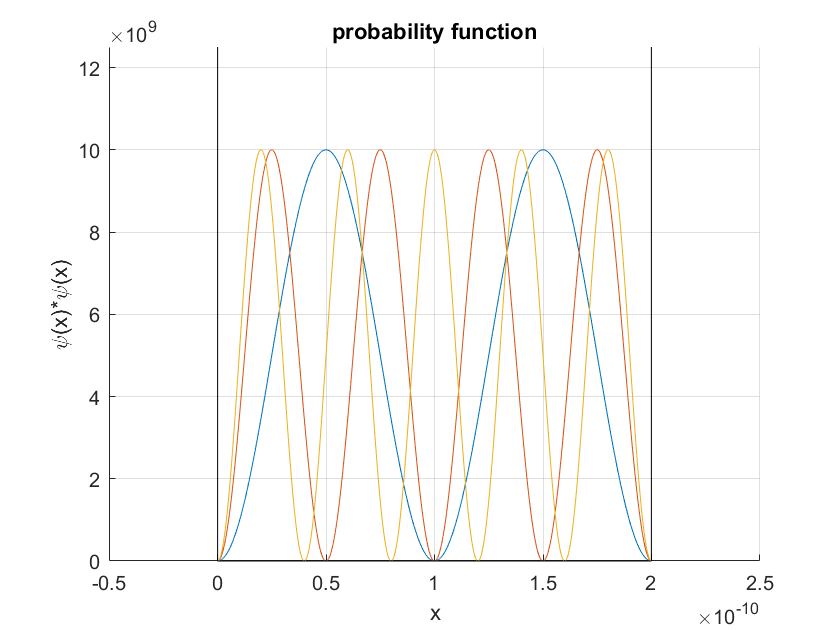


% probability function setup

figure
hold on;
if size_n(2) == 1
    plot(x,psiSTARpsi);
else
    for c = 1 : size_n(2)
        plot(x,psiSTARpsi(c,:));
    end
end

plot(xU,U,'black'); % potential plot
hold off;

% probability function plot labels and such

title('probability function');ylabel('\psi(x)*\psi(x)');
xlabel('x');
axis([-a/4,a+a/4, ...
    min(min(psiSTARpsi)) + min(min(psiSTARpsi))/4, ...
    max(max(psiSTARpsi)) + max(max(psiSTARpsi))/4])
grid on;